# MATLAB-Python Workflow to Predict Masked SMILES Tokens Using BERT   

### Introduction

This simple example demonstrates how [Python-MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html) can work together for molecular structure processing. The task is to predict masked tokens using a pretrained [BERT](https://huggingface.co/transformers/v3.0.2/index.html) model. BERT models are trained to perform various tasks. One of the tasks is known as masked language modeling which is the task of predicting token in text that have been replaced by a mask value. This example shows how to predict masked tokens for text data and calculate the token probabilities using a pretrained BERT model.  

### Requirements

This example requires [DeepChem](https://deepchem.io/) [1] ([MIT License](https://github.com/deepchem/deepchem/blob/master/LICENSE)), which can be installed by running the following command. 

`       pip` `install` `deepchem`

This example uses some of the functions from [RDKit](https://www.rdkit.org/) [2] ([BSD 3-Clause License](https://github.com/rdkit/rdkit/blob/master/license.txt)). RDKit can be installed easily by following its [installation](https://www.rdkit.org/docs/Install.html) instructions on Linux, Windows, and macOS. You can install RDKit using pip.

`       pip` `install`` rdkit`

Make sure to give the python address and to check versions of Python compatible with MATLAB products by release. This allows to build proper [MATLAB Interface to Python](https://www.mathworks.com/support/requirements/python-compatibility.html).

clear;
clc;
close all;

pyenv("Version","C:\Users\...\python.exe");

### Input molecule and visualize

Provide the SMILES sting. You can also provide the substructure you would like to highlight in the molecule.

SMILES="CCN(CC)C(=O)c1cccnc1";
Mask="CCN";
Masked_SMILES = "<mask>(CC)C(=O)c1cccnc1";

strfind(SMILES,Mask)

ans = 1

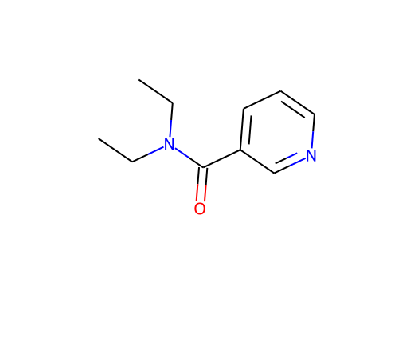

res0 = pyrunfile("ChemMolFromSmiles.py","mol0",x=SMILES);
img0 = string(res0);
rgbImage0 = imread(img0);
imshow(rgbImage0)

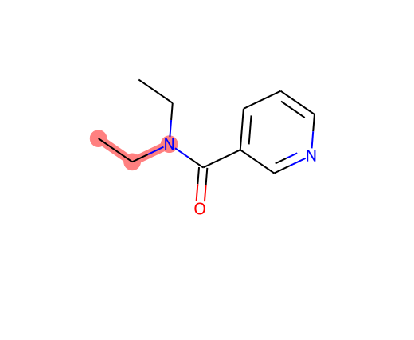

res1 = pyrunfile("GetSubstructMatch.py","mol1",x=SMILES,y=Mask);
img1 = string(res1);
rgbImage1 = imread(img1);
imshow(rgbImage1)

### Load Pretrained BERT Model

Load a pretrained BERT model using the |bert| function [3]. The model consists of a tokenizer that encodes text as sequences of integers, and a structure of parameters.

Model = pyrunfile("Py_Chem_Model.py","moldel");

C:\Users\hjooya\AppData\Local\Continuum\anaconda3\envs\DeepChem-env\lib\site-packages\transformers\models\auto\modeling_auto.py:1132: FutureWarning: The class `AutoModelWithLMHead` is deprecated and will be removed in a future version. Please use `AutoModelForCausalLM` for causal language models, `AutoModelForMaskedLM` for masked language models and `AutoModelForSeq2SeqLM` for encoder-decoder models.
  warnings.warn(


Tokenizer = pyrunfile("Py_Chem_Tokenizer.py","tokenizer");

### Predict Masked Token

Predict the masked token using the |predictMaskedToken| function. The function returns the original string with the mask tokens replaced.

pyrunfile("Py_Chem_Predict.py",smiles_mask=Masked_SMILES);

{'score': 0.3347172439098358, 'token': 267, 'token_str': 'CCC', 'sequence': 'CCC(CC)C(=O)c1cccnc1'}
{'score': 0.24358177185058594, 'token': 289, 'token_str': 'CCN', 'sequence': 'CCN(CC)C(=O)c1cccnc1'}
{'score': 0.13082949817180634, 'token': 293, 'token_str': 'CCCCC', 'sequence': 'CCCCC(CC)C(=O)c1cccnc1'}
{'score': 0.06048673018813133, 'token': 373, 'token_str': 'CCCCN', 'sequence': 'CCCCN(CC)C(=O)c1cccnc1'}
{'score': 0.040443334728479385, 'token': 621, 'token_str': 'CCOCCN', 'sequence': 'CCOCCN(CC)C(=O)c1cccnc1'}


### References

[1] [MoleculeNet](https://arxiv.org/abs/1703.00564): A Benchmark for Molecular Machine Learning

[2] RDKit: Open-source cheminformatics; [http://www.rdkit.org](https://www.rdkit.org/)

[3] [Transformers: State-of-the-Art Natural Language Processing](https://aclanthology.org/2020.emnlp-demos.6/).